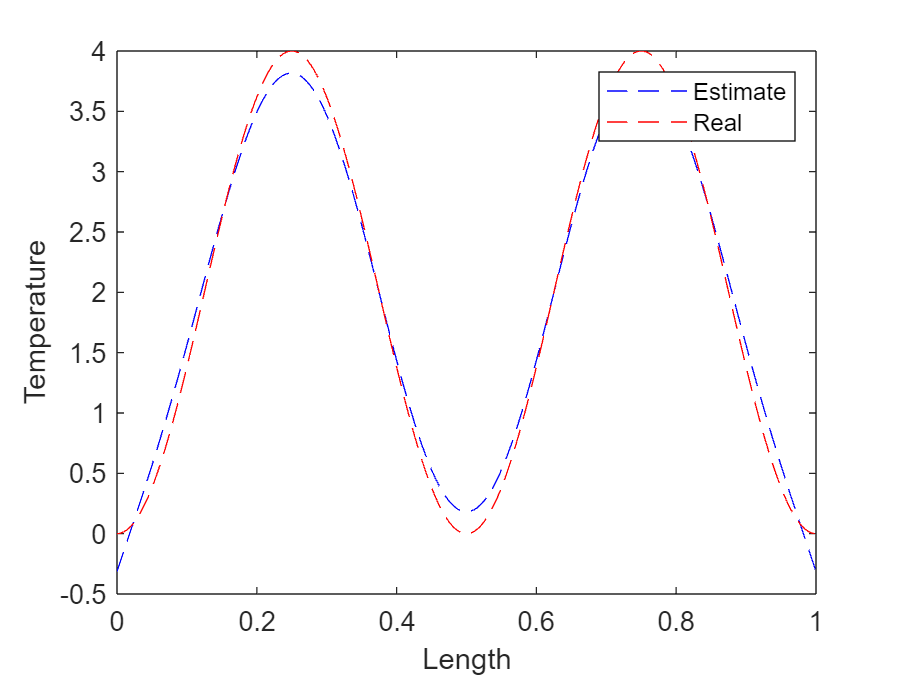

% N
n_1=500;


% Interval
h_1=1/n_1;

% X-axis
x_1=0:h_1:1;

% u hat matrix
u_hat=zeros(n_1+1,1);
for i=1:n_1+1
    u_hat(i,1)=2*sin(4*pi*x_1(1,i)+3/2*pi)+2;
end

% M matrix
M=eye(n_1+1);

% K matrix
K_1=zeros(n_1+1,n_1+1);
for i=1:n_1+1
    for j=1:n_1+1
        % overlapping condition 1
        if i==j
            if i==1
                K_1(i,j)=n_1-100;
            elseif i==n_1+1
                K_1(i,j)=n_1-100;
            else
                K_1(i,j)=n_1*2;
            end
        % overlapping condition 2
        elseif j-i==1
            if i==1
                K_1(i,j)=-n_1+50;
            else
                K_1(i,j)=-n_1;
            end
        elseif i-j==1
            if i==n_1+1
                K_1(i,j)=-n_1+50;
            else
                K_1(i,j)=-n_1;
            end
        end
    end
end

% u matrix
u = sym('a', [n_1+1,1]);

% f matrix
f=sym('b',[n_1+1,1]);

% lambda matrix
lambda=sym('l',[n_1+1,1]);

% J equantion
J=1/2*(u-u_hat)'*M*(u-u_hat)+1/2*f'*M*f;

% KU-f
exp2=K_1*u-f;

% Lagrange
L = J + lambda'* exp2;

% KKT
grad_A = gradient(L, u);
grad_f = gradient(L, f);
grad_lambda = gradient(L, lambda);

% Solving
%none=zeros(n_1+1,1)
eqns = [grad_A == 0; grad_f == 0; grad_lambda == 0];
sol = vpasolve(eqns);

% Result
A_sol = double(subs(u, fieldnames(sol), struct2cell(sol)));
f_sol = double(subs(f, fieldnames(sol), struct2cell(sol)));
lambda_sol = double(subs(lambda,fieldnames(sol), struct2cell(sol)));

% Temperature
figure;
plot( x_1, A_sol, 'b--',x_1,u_hat,'r--');
xlabel('Length'); ylabel('Temperature');
legend('Estimate','Real');

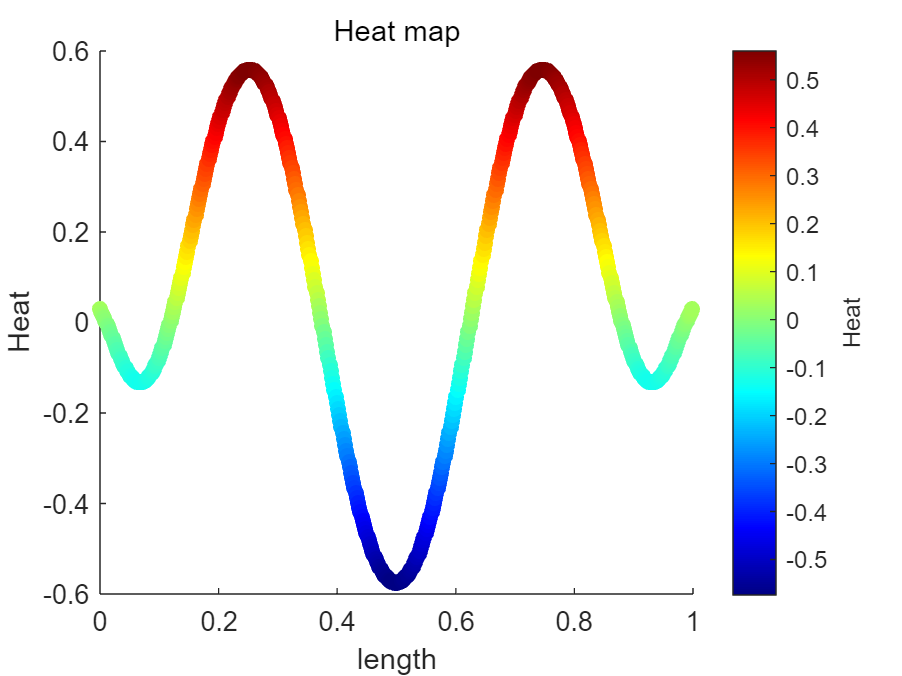


% Heat
figure;
scatter(x_1, f_sol, 36, f_sol, 'filled');

colorbar;
colormap(jet);

xlabel('length');
ylabel('Heat');
title('Heat map');


c = colorbar;
c.Label.String = 'Heat';